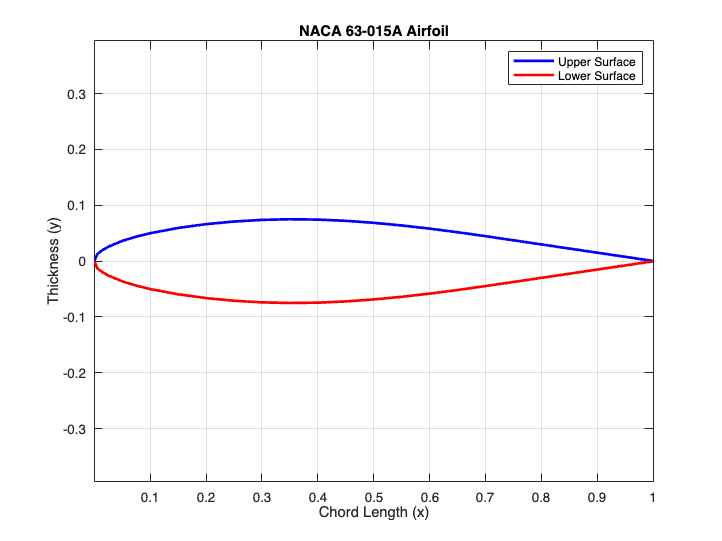

% NACA 63-015A Airfoil Plot

% Upper surface coordinates
x_upper = [0.000000 0.005000 0.007500 0.012500 0.025000 0.050000 0.075000 ...
           0.100000 0.150000 0.200000 0.250000 0.300000 0.350000 0.400000 ...
           0.450000 0.500000 0.550000 0.600000 0.650000 0.700000 0.750000 ...
           0.800000 0.850000 0.900000 0.950000 1.000000];
y_upper = [0.000000 0.012030 0.014480 0.018440 0.025790 0.036180 0.043820 ...
           0.049970 0.059420 0.066190 0.070910 0.073840 0.074960 0.074350 ...
           0.072150 0.068580 0.063870 0.058200 0.051730 0.044680 0.037310 ...
           0.029910 0.022520 0.015120 0.007720 0.000320];

% Lower surface coordinates
x_lower = [0.000000 0.005000 0.007500 0.012500 0.025000 0.050000 0.075000 ...
           0.100000 0.150000 0.200000 0.250000 0.300000 0.350000 0.400000 ...
           0.450000 0.500000 0.550000 0.600000 0.650000 0.700000 0.750000 ...
           0.800000 0.850000 0.900000 0.950000 1.000000];
y_lower = [0.000000 -0.012030 -0.014480 -0.018440 -0.025790 -0.036180 -0.043820 ...
           -0.049970 -0.059420 -0.066190 -0.070910 -0.073840 -0.074960 -0.074350 ...
           -0.072150 -0.068580 -0.063870 -0.058200 -0.051730 -0.044680 -0.037310 ...
           -0.029910 -0.022520 -0.015120 -0.007720 -0.000320];

% Plot airfoil shape
figure;
plot(x_upper, y_upper, 'b', 'LineWidth', 2); % Upper surface
hold on;
plot(x_lower, y_lower, 'r', 'LineWidth', 2); % Lower surface
grid on;
axis equal; % Keep the aspect ratio
xlabel('Chord Length (x)');
ylabel('Thickness (y)');
title('NACA 63-015A Airfoil');
legend('Upper Surface', 'Lower Surface');


% Enable scaling with zoom and axis commands
disp('Use "axis([xmin xmax ymin ymax])" to scale manually.');

Use "axis([xmin xmax ymin ymax])" to scale manually.


disp('Use zoom function in MATLAB to interactively scale the plot.');

Use zoom function in MATLAB to interactively scale the plot.


First section which helps calculate the number of plies needed

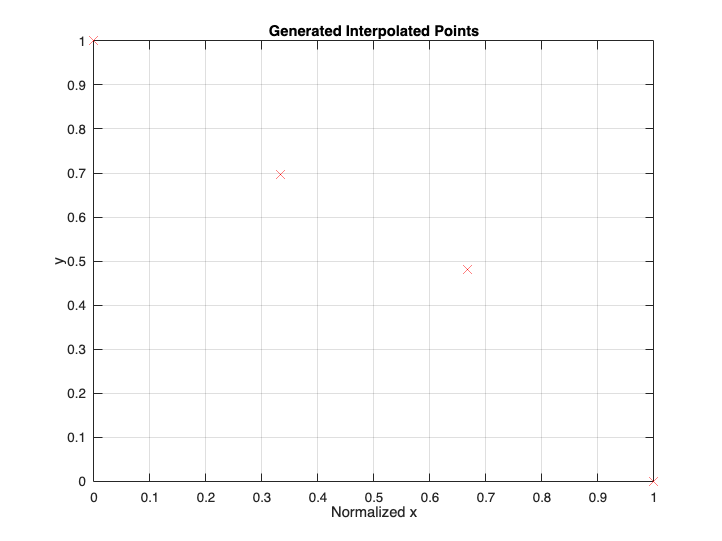

x_generated =          0    0.3333    0.6667    1.0000


y_generated =     1.0000    0.6965    0.4814         0


clear; clc; clf;
% Define symbolic variable
syms z L_vs b_VS

% Define Ldash_vs as a symbolic expression
Ldash_vs = (4 * L_vs / (pi * b_VS)) * sqrt(1 - (z / b_VS)^2);

% Perform symbolic integration
shear_result = int(Ldash_vs, z);
moment_result = int(shear_result, z);

% Set values for L and span
L = 89039;
span = 26.41;
n_values = [3.75, -1.5];
colors = ['b', 'g', 'r']; % Colors for different n-values
% panel size and loading
omega = L / span / 2; % (N/m)
b = 0.05; % (m)
h = 0.1; % (m)
c = 0.4; % (m)
a = 0.3; % (m)

% Set the range for z and initialize results
N = 4;
z_vals = linspace(span / 2, 0, N);
force_vals = zeros(N, length(n_values));
shear_vals = zeros(N, length(n_values));
moment_vals = zeros(N, length(n_values));
htailplane_mass = 2981.5;
vtailplane_mass = 2688.32;
htailplane_mass_dis = linspace(0, htailplane_mass, N);
vtailplane_mass_dis = linspace(0, vtailplane_mass, N);

% Loop over different load factors
for j = 1:length(n_values)
    n = n_values(j);
    force_result_numeric = subs(Ldash_vs, [L_vs, b_VS], [L * n, span / 2]);
    shear_result_numeric = subs(shear_result, [L_vs, b_VS], [L * n, span / 2]);
    moment_result_numeric = subs(moment_result, [L_vs, b_VS], [L * n, span / 2]);
    moment_before = 0;
    
    for i = 1:N
        z_current = z_vals(i);
        force_vals(i, j) = real(double(subs(force_result_numeric, z, span/2))) - real(double(subs(force_result_numeric, z, z_current)));
        shear_vals(i, j) = real(double(subs(shear_result_numeric, z, span/2))) - real(double(subs(shear_result_numeric, z, z_current)));
        if i > 1
            moment_vals(i, j) = (shear_vals(i, j) + shear_vals(i - 1, j)) / (span/2/N) + moment_before;
            moment_before = moment_vals(i, j);
        end
    end
end


[x_generated, y_generated] = generate_interpolated_points(N)


cref = 4.24

cref = 4.2400

a =  (0.6 + 0.12) * cref  / 2 - 0.25 * cref;
a = a / 2; % assume from spreadsheet that a = b1 = half of distance between singbox and load centre
root_c = y_generated;
b1 = a;


AoA = 7.5 - 0.15;
CM_a = -0.5;
CM_0 = 0.13;
Sref = 110.4;
Vau = 651;
M_0 = (AoA / 57.3 * CM_a + CM_0) * Sref * cref * 0.5 * 1.225 * (Vau / 3.6)^2

M_0 = 6.1751e+05

ht_mass = 2981;

lift_moment_dis = -root_c'.*flip(force_vals(:, 1),1)* a 

lift_moment_dis = 1.0e+03 *

    7.5078
    4.9303
    2.6941
         0



pitching_moment_dis = zeros(4,1);

for i = 1:size(force_vals,1)
    pitching_moment_dis(i,1) = M_0 * force_vals(i, 1) ./ (2*sum(force_vals(:,1))*0.1);
end
pitching_moment_dis = flip(pitching_moment_dis)

pitching_moment_dis = 1.0e+06 *

    1.1486
    1.0829
    0.8561
         0



ht_weight_moment_dis(:,1) = ht_mass .* root_c .* b1 .* 9.81 * 3.75 .* span / 2

ht_weight_moment_dis = 1.0e+05 *

    3.3770
    2.3521
    1.6258
         0



for i = 1:size(lift_moment_dis,1) - 1
    lift_moment_int(i) = (lift_moment_dis(i+1,1) + lift_moment_dis(i,1)) / (z_vals(i + 1) - z_vals(i))
    pitching_moment_int(i) = (pitching_moment_dis(i+1,1) + pitching_moment_dis(i,1)) / (z_vals(i + 1) - z_vals(i));
    ht_weight_moment_int(i) = (ht_weight_moment_dis(i+1,1) + ht_weight_moment_dis(i,1)) / (z_vals(i + 1) - z_vals(i));
    combined_moment_temp(i) = lift_moment_int(i) + pitching_moment_int(i)*1000 + ht_weight_moment_int(i);
end

lift_moment_int = -2.8258e+03

lift_moment_int = 1.0e+03 *

   -2.8258   -1.7321


lift_moment_int = 1.0e+03 *

   -2.8258   -1.7321   -0.6121


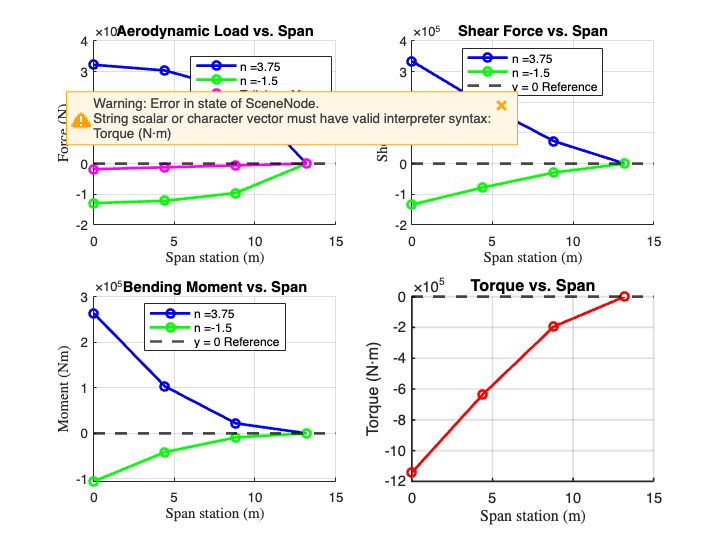

combined_moment_temp = [flip(cumsum(flip(combined_moment_temp))), 0]./10^3;

% Define colors for different load factors
colors = ['b', 'g', 'r']; 
legend_entries = strcat('n = ', string(n_values));

% Create figure with subplots
figure;
set(gcf, 'Position', [100, 100, 800, 600]); % Adjust figure size

% Aerodynamic Load vs. Span
subplot(2, 2, 1);
hold on;
for j = 1:length(n_values)
    plot(z_vals, -force_vals(:, j), strcat(colors(j), '-o'), 'LineWidth', 2);
end
plot(z_vals, -htailplane_mass_dis * 9.81 * 3.75 / 60, 'm-o', 'LineWidth', 2);
yline(0, 'k--', 'LineWidth', 2);
title('Aerodynamic Load vs. Span');
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Force (N)', 'Interpreter', 'latex');
grid on;
legend([legend_entries, 'Tailplane Mass', 'y = 0 Reference'], 'Location', 'Best');

% Shear Force vs. Span
subplot(2, 2, 2);
hold on;
for j = 1:length(n_values)
    plot(z_vals, shear_vals(:, j), strcat(colors(j), '-o'), 'LineWidth', 2);
end
yline(0, 'k--', 'LineWidth', 2);
title('Shear Force vs. Span');
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Shear (N)', 'Interpreter', 'latex');
grid on;
legend([legend_entries, 'y = 0 Reference'], 'Location', 'Best');

% Bending Moment vs. Span
subplot(2, 2, 3);
hold on;
for j = 1:length(n_values)
    plot(z_vals, moment_vals(:, j), strcat(colors(j), '-o'), 'LineWidth', 2);
end
yline(0, 'k--', 'LineWidth', 2);
title('Bending Moment vs. Span');
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Moment (Nm)', 'Interpreter', 'latex');
grid on;
legend([legend_entries, 'y = 0 Reference'], 'Location', 'Best');

% Torque vs. Span
subplot(2, 2, 4);
plot(z_vals, flip(combined_moment_temp), 'r-o', 'LineWidth', 2);
hold on;
yline(0, 'k--', 'LineWidth', 2);
title('Torque vs. Span');
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Torque (N·m)', 'Interpreter', 'latex');
grid on;

% Set global axis properties
set(gca, 'FontSize', 11, 'LineWidth', 1.25, 'Box', 'off');


%change direction of lift distribution

Vertical Tailplane

clear; clc; clf;
% Define symbolic variable
syms z L_vt b_vt

% Define Ldash_vt as a symbolic expression
Ldash_vt = (4 * L_vt / (pi * b_vt)) * sqrt(1 - (z / b_vt)^2);

% Perform symbolic integration
shear_result_vt = int(Ldash_vt, z);
moment_result_vt = int(shear_result_vt, z);

% Set values for L and span
L_vt_val = 89039;
span_vt = 26.41;
n_values = [3.75, -1.5];
colors = ['b', 'g', 'r']; % Colors for different n-values

% Panel size and loading
omega_vt = L_vt_val / span_vt / 2; % (N/m)
b_vt_panel = 0.05; % (m)
h_vt = 0.1; % (m)
c_vt = 0.4; % (m)
a_vt = 0.3; % (m)

% Set the range for z and initialize results
N = 4;
z_vals_vt = linspace(span_vt / 2, 0, N);
force_vals_vt = zeros(N, length(n_values));
shear_vals_vt = zeros(N, length(n_values));
moment_vals_vt = zeros(N, length(n_values));

vtailplane_mass = 2688.32;
vtailplane_mass_dis = linspace(0, vtailplane_mass, N);

% Loop over different load factors
for j = 1:length(n_values)
    n = n_values(j);
    force_result_numeric_vt = subs(Ldash_vt, [L_vt, b_vt], [L_vt_val * n, span_vt / 2]);
    shear_result_numeric_vt = subs(shear_result_vt, [L_vt, b_vt], [L_vt_val * n, span_vt / 2]);
    moment_result_numeric_vt = subs(moment_result_vt, [L_vt, b_vt], [L_vt_val * n, span_vt / 2]);
    moment_before_vt = 0;
    
    for i = 1:N
        z_current_vt = z_vals_vt(i);
        force_vals_vt(i, j) = real(double(subs(force_result_numeric_vt, z, span_vt/2))) - real(double(subs(force_result_numeric_vt, z, z_current_vt)));
        shear_vals_vt(i, j) = real(double(subs(shear_result_numeric_vt, z, span_vt/2))) - real(double(subs(shear_result_numeric_vt, z, z_current_vt)));
        if i > 1
            moment_vals_vt(i, j) = (shear_vals_vt(i, j) + shear_vals_vt(i - 1, j)) / (span_vt/2/N) + moment_before_vt;
            moment_before_vt = moment_vals_vt(i, j);
        end
    end
end

[x_generated_vt, y_generated_vt] = generate_interpolated_points(N);

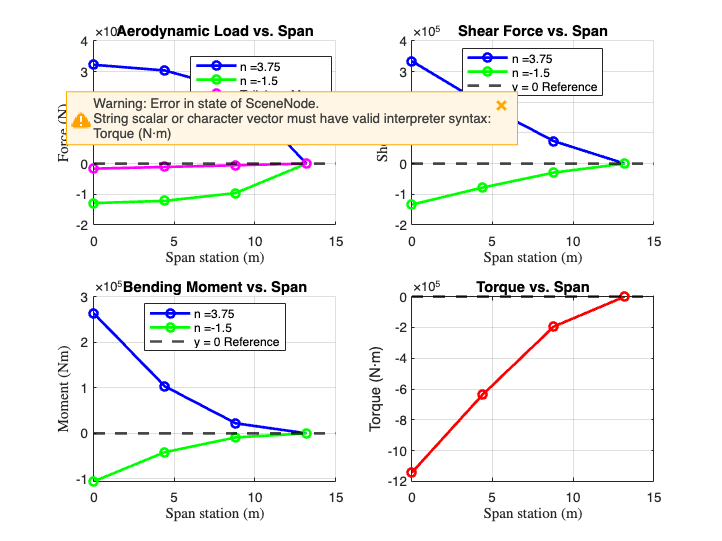


cref_vt = 4.24;
a_vt =  (0.6 + 0.12) * cref_vt  / 2 - 0.25 * cref_vt;
a_vt = a_vt / 2; % Assume from spreadsheet that a_vt = b1_vt = half of distance between singbox and load centre
root_c_vt = y_generated_vt;
b1_vt = a_vt;

AoA_vt = 7.5 - 0.15;
CM_a_vt = -0.5;
CM_0_vt = 0.13;
Sref_vt = 110.4;
Vau_vt = 651;
M_0_vt = (AoA_vt / 57.3 * CM_a_vt + CM_0_vt) * Sref_vt * cref_vt * 0.5 * 1.225 * (Vau_vt / 3.6)^2;

vt_mass = 2688.32;

lift_moment_dis_vt = -root_c_vt' .* flip(force_vals_vt(:, 1), 1) * a_vt;

pitching_moment_dis_vt = zeros(4,1);

for i = 1:size(force_vals_vt, 1)
    pitching_moment_dis_vt(i,1) = M_0_vt * force_vals_vt(i, 1) ./ (2*sum(force_vals_vt(:,1))*0.1);
end
pitching_moment_dis_vt = flip(pitching_moment_dis_vt);

vt_weight_moment_dis(:,1) = vt_mass .* root_c_vt .* b1_vt .* 9.81 * 3.75 .* span_vt / 2;

for i = 1:size(lift_moment_dis_vt, 1) - 1
    lift_moment_int_vt(i) = (lift_moment_dis_vt(i+1,1) + lift_moment_dis_vt(i,1)) / (z_vals_vt(i + 1) - z_vals_vt(i));
    pitching_moment_int_vt(i) = (pitching_moment_dis_vt(i+1,1) + pitching_moment_dis_vt(i,1)) / (z_vals_vt(i + 1) - z_vals_vt(i));
    vt_weight_moment_int(i) = (vt_weight_moment_dis(i+1,1) + vt_weight_moment_dis(i,1)) / (z_vals_vt(i + 1) - z_vals_vt(i));
    combined_moment_temp_vt(i) = lift_moment_int_vt(i) + pitching_moment_int_vt(i) * 1000 + vt_weight_moment_int(i);
end
combined_moment_temp_vt = [flip(cumsum(flip(combined_moment_temp_vt))), 0]./10^3;

% Define colors for different load factors
colors = ['b', 'g', 'r']; 
legend_entries = strcat('n = ', string(n_values));

% Create figure with subplots
figure;
set(gcf, 'Position', [100, 100, 800, 600]); % Adjust figure size

% Aerodynamic Load vs. Span
subplot(2, 2, 1);
hold on;
for j = 1:length(n_values)
    plot(z_vals_vt, -force_vals_vt(:, j), strcat(colors(j), '-o'), 'LineWidth', 2);
end
plot(z_vals_vt, -vtailplane_mass_dis * 9.81 * 3.75 / 60, 'm-o', 'LineWidth', 2);
yline(0, 'k--', 'LineWidth', 2);
title('Aerodynamic Load vs. Span');
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Force (N)', 'Interpreter', 'latex');
grid on;
legend([legend_entries, 'Tailplane Mass', 'y = 0 Reference'], 'Location', 'Best');

% Shear Force vs. Span
subplot(2, 2, 2);
hold on;
for j = 1:length(n_values)
    plot(z_vals_vt, shear_vals_vt(:, j), strcat(colors(j), '-o'), 'LineWidth', 2);
end
yline(0, 'k--', 'LineWidth', 2);
title('Shear Force vs. Span');
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Shear (N)', 'Interpreter', 'latex');
grid on;
legend([legend_entries, 'y = 0 Reference'], 'Location', 'Best');

% Bending Moment vs. Span
subplot(2, 2, 3);
hold on;
for j = 1:length(n_values)
    plot(z_vals_vt, moment_vals_vt(:, j), strcat(colors(j), '-o'), 'LineWidth', 2);
end
yline(0, 'k--', 'LineWidth', 2);
title('Bending Moment vs. Span');
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Moment (Nm)', 'Interpreter', 'latex');
grid on;
legend([legend_entries, 'y = 0 Reference'], 'Location', 'Best');

% Torque vs. Span
subplot(2, 2, 4);
plot(z_vals_vt, flip(combined_moment_temp_vt), 'r-o', 'LineWidth', 2);
hold on;
yline(0, 'k--', 'LineWidth', 2);
title('Torque vs. Span');
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Torque (N·m)', 'Interpreter', 'latex');
grid on;

Second section which helps calculate the best order for plies

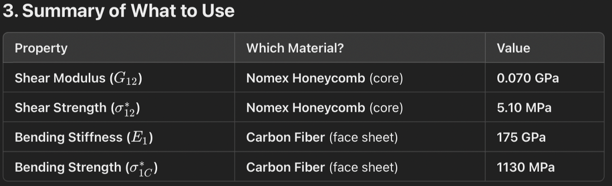

for i = 1:length(n_values)
    n = n_values(i);
    
    % panel size and loading
    omega = L / span / 2; % (N/m)
    b = 0.05; % (m)
    h = 0.1; % (m)
    c = 0.4; % (m)
    a = 0.3; % (m)
    
    % properties per ply
    t = 6e-4; % ply thickness
    sigma_c = 1130e7; % strength in compression
    tau_xy = 5.1e7; % strength in shear
    a_b = a / b; % panel aspect ratio
    
    % axial load / unit length
    Nx = moment_vals ./ (h * c); % Adjusted for n
    
    % Initialize storage for each row of shear_vals
    covers_and_webs_tables = cell(size(shear_vals, 1), 1);
    
    for j = 1:size(shear_vals, 1) % Loop through rows of shear_vals
        % COVERS
        eta_c0 = shear_vals(j, i) ./ (h * c) ./ (sigma_c * t);
        no_plys0degcovers = ceil(max(abs(eta_c0)));
        thickness0degcovers = no_plys0degcovers * t;

        no_plys90degcovers = 2 * ceil(no_plys0degcovers * 0.1);
        thickness90degcovers = no_plys90degcovers * t;

        no_plys45degcovers = 2 * ceil(no_plys0degcovers * 0.1);
        thickness45degcovers = no_plys45degcovers * t;

        % WEBS
        eta_s = 0.5 * shear_vals(j, i) ./ (tau_xy * t * h);
        no_plys45degwebs = 2 * ceil(max(abs(eta_s)));
        thickness45degwebs = no_plys45degwebs * t;

        no_plys0degwebs = 2 * ceil(no_plys45degwebs * 0.1);
        thickness0degwebs = no_plys0degwebs * t;

        no_plys90degwebs = 2 * ceil(no_plys45degwebs * 0.1);
        thickness90degwebs = no_plys90degwebs * t;

        % Create a table with the results
        covers_and_webs_table = table(...
            {'0deg covers'; '90deg covers'; '45deg covers'; '45deg webs'; '0deg webs'; '90deg webs'}, ...
            [thickness0degcovers; thickness90degcovers; thickness45degcovers; thickness45degwebs; thickness0degwebs; thickness90degwebs], ...
            round([no_plys0degcovers; no_plys90degcovers; no_plys45degcovers; no_plys45degwebs; no_plys0degwebs; no_plys90degwebs]), ...
            'VariableNames', {'Ply_Type', 'Ply_Thickness_m', 'No_Plys'});

        % Format the No_Plys column to display as integers
        covers_and_webs_table.No_Plys = uint8(covers_and_webs_table.No_Plys); % Convert to integer type

        % Store results for each row
        covers_and_webs_tables{j} = covers_and_webs_table;
        
        fprintf('Results for n = %.2f, row %d of shear_vals:\n', n, j);
        disp(covers_and_webs_table);
    end
end

Unrecognized function or variable 'L'.

% Define ply types, thickness, and number of plies
plies = [
    struct('ply_type', 'deg0', 'ply_thickness', 0.0005, 'ply_count', 20, 'stack', struct());
    struct('ply_type', 'deg90', 'ply_thickness', 0.0005, 'ply_count', 4, 'stack', struct());
    struct('ply_type', 'deg45', 'ply_thickness', 0.0005, 'ply_count', 8, 'stack', struct());
];


plies_station_I = [
    struct('ply_type','deg0','ply_thickness', 0.0005, 'ply_count', 36, 'span_lower', 0, 'span_upper', 10,'stack', 0),
    struct('ply_type','deg90', 'ply_thickness', 0.0005, 'ply_count', 8, 'span_lower', 0, 'span_upper', 10,'stack', 0),
    struct('ply_type','deg45', 'ply_thickness', 0.0005, 'ply_count', 8, 'span_lower', 0, 'span_upper', 10,'stack', 0) 
    ]

plies_station_II = [...
    struct('ply_type','deg0','ply_thickness', 0.0005, 'ply_count', 14, 'span_lower', 10, 'span_upper', 15,'stack', 0),
    struct('ply_type','deg90', 'ply_thickness', 0.0005, 'ply_count', 8, 'span_lower', 10, 'span_upper', 15,'stack', 0),
    struct('ply_type','deg45', 'ply_thickness', 0.0005, 'ply_count', 8, 'span_lower', 10, 'span_upper', 15,'stack', 0)
    ]

plies_station_III = [
    struct('ply_type','deg0','ply_thickness', 0.0005, 'ply_count', 8, 'span_lower', 15, 'span_upper', 20,'stack', 0),
    struct('ply_type','deg90', 'ply_thickness', 0.0005, 'ply_count', 8, 'span_lower', 15, 'span_upper', 20,'stack', 0), 
    struct('ply_type','deg45', 'ply_thickness', 0.0005, 'ply_count', 10, 'span_lower', 15, 'span_upper', 20,'stack', 0) 
]





% Create the main struct to hold all stations
plies_struct = struct( ...
    'station_I', plies_station_I, ...
    'station_II', plies_station_II, ...
    'station_III', plies_station_III ...
);
stations = fieldnames(plies_struct);

N = size(stations,1); % Example number of elements
stack = repmat(struct('data', []), N, 1) % Initialize struct array


for l = 1:size(stations,1)
    % Initialize variables to track the number of plies in each direction
    ply_count = struct('deg0', 0, 'deg90', 0, 'deg45', 0);
    
    stations = fieldnames(plies_struct)

    current_station = plies_struct.(stations{l});
   
    % Initialize stack variable
    temp_stack = [];
    
    % Track remaining plies to add
    remaining_ply_count = [plies_struct.(stations{l})(1).ply_count, plies_struct.(stations{l})(2).ply_count, plies_struct.(stations{l})(3).ply_count];
    
    % Define symmetry condition
    total_layers = sum(remaining_ply_count);
    
    span_lower_values = [current_station.span_lower];
    span_upper_values = [current_station.span_upper];


    % Loop until all plies are added
    while remaining_ply_count(1) > 0 || remaining_ply_count(2) > 0 || remaining_ply_count(3) > 0  % Continue until all plies are used
        added_ply = false;  % Flag to check if a ply was added in this iteration
        % Add 45 degree plies (1 at a time for symmetry)
        if remaining_ply_count(3) > 0
            if size(temp_stack) == 0
                % Place ply symmetrically
                ply = struct('ply_type', 'deg45', 'ply_thickness', 0.0005, 'lower_span', span_lower_values(3), 'upper_span', span_upper_values(3));
                temp_stack = [ply, temp_stack, ply];  % Insert at both ends for symmetry
                ply_count.deg45 = ply_count.deg45 + 2;
                remaining_ply_count(3) = remaining_ply_count(3) - 2;
                added_ply = true;
            elseif remaining_ply_count(3) > 0 && length(temp_stack) >= 2 && strcmp(temp_stack(end-1).ply_type, 'deg45') && strcmp(temp_stack(end).ply_type, 'deg45')
                % Place ply symmetrically
                ply = struct('ply_type', 'deg90', 'ply_thickness', 0.0005, 'lower_span', span_lower_values(2), 'upper_span', span_upper_values(2));
                temp_stack = [ply, temp_stack, ply];  % Insert at both ends for symmetry
                if remaining_ply_count(3) > 2
                    ply_count.deg90 = ply_count.deg90 + 2;
                    remaining_ply_count(2) = remaining_ply_count(2) - 2;
                    added_ply = true;
                else
                    ply_count.deg90 = ply_count.deg90 + 2;
                    added_ply = true;
                end 
                % Place ply symmetrically
            elseif remaining_ply_count(3) >= 4
                ply = struct('ply_type', 'deg45', 'ply_thickness', 0.0005, 'lower_span', span_lower_values(3), 'upper_span', span_upper_values(3));
                temp_stack = [ply, ply, temp_stack, ply, ply];  % Insert at both ends for symmetry
                ply_count.deg45 = ply_count.deg45 + 4;
                remaining_ply_count(3) = remaining_ply_count(3) - 4;
                added_ply = true;           
            else
                remaining_ply_count(3) == 0;
                % Place ply symmetrically
                ply = struct('ply_type', 'deg45', 'ply_thickness', 0.0005, 'lower_span', span_lower_values(3), 'upper_span', span_upper_values(3));
                temp_stack = [ply, temp_stack, ply];  % Insert at both ends for symmetry
                ply_count.deg45 = ply_count.deg45 + 2;
                remaining_ply_count(3) = remaining_ply_count(3) - 2;
                added_ply = true;
            end
        end
    
    
        % Add 90 degree plies (1 at a time for symmetry)
        if remaining_ply_count(2) > 0
            % Place ply symmetrically
            ply = struct('ply_type', 'deg90', 'ply_thickness', 0.0005, 'lower_span',span_lower_values(2), 'upper_span', span_upper_values(2));
            temp_stack = [ply, temp_stack, ply];  % Insert at both ends for symmetry
            ply_count.deg90 = ply_count.deg90 + 2;
            remaining_ply_count(2) = remaining_ply_count(2) - 2;
            added_ply = true;
    
            % Always add a deg0 ply between deg90 and deg45 if needed
            if remaining_ply_count(3) > 0 && length(temp_stack) >= 2 && strcmp(temp_stack(end-1).ply_type, 'deg90') && strcmp(temp_stack(end).ply_type, 'deg45')
                ply = struct('ply_type', 'deg0', 'ply_thickness', 0.0005, 'lower_span', span_lower_values(1), 'upper_span', span_upper_values(1));
                temp_stack = [ply, temp_stack, ply];  % Insert at both ends for symmetry
                ply_count.deg0 = ply_count.deg0 + 2;
                remaining_ply_count(1) = remaining_ply_count(1) - 2;
                added_ply = true;
            end
        end
    
            % Add 0 degree plies (1 at a time for symmetry)
        while remaining_ply_count(1) > 0
            % Check if adding another 0° ply will create more than 2 consecutive 0° plies
            if length(temp_stack) >= 2 && strcmp(temp_stack(end-1).ply_type, 'deg0') && strcmp(temp_stack(end).ply_type, 'deg0')
                if remaining_ply_count(2) == 0
                    ply = struct('ply_type', 'deg90', 'ply_thickness', 0.0005, 'lower_span', span_lower_values(2), 'upper_span', span_upper_values(2));
                    temp_stack = [ply, temp_stack, ply];  % Insert at both ends for symmetry
                    ply_count.deg90 = ply_count.deg90 + 2;
                    % remaining_ply_count(2) = remaining_ply_count(2) - 2;
                    added_ply = true;
                else 
                    ply = struct('ply_type', 'deg90', 'ply_thickness', 0.0005, 'lower_span', span_lower_values(2), 'upper_span', span_upper_values(2));
                    temp_stack = [ply, temp_stack, ply];  % Insert at both ends for symmetry
                    ply_count.deg90 = ply_count.deg90 + 2;
                    remaining_ply_count(2) = remaining_ply_count(2) - 2;
                    added_ply = true;
                end
            else
                % Place ply symmetrically
                ply = struct('ply_type', 'deg0', 'ply_thickness', 0.0005, 'lower_span', span_lower_values(1), 'upper_span', span_upper_values(1));
                temp_stack = [ply, temp_stack, ply];  % Insert at both ends for symmetry
                ply_count.deg0 = ply_count.deg0 + 2;
                remaining_ply_count(1) = remaining_ply_count(1) - 2;
                added_ply = true;
            end
        end
            
        % If no ply was added, break the loop to avoid an infinite loop
        if ~added_ply
            break
        end
    end
    % Assign the temporary stack to the correct index
    stack(l).data = temp_stack; % Assign the 1x40 struct array to each element

    % Display results
    disp('Final stack of plies (symmetrical):');
    for i = 1:length(temp_stack)
        disp(['Ply ', num2str(i), ': ', temp_stack(i).ply_type, ' Thickness: ', num2str(temp_stack(i).ply_thickness)]);
    end
    disp('Ply counts by direction:');
    disp(ply_count);
end  



% Define colors for each ply orientation
colors = struct('deg0', [0, 0.5, 0], ...   % Green for 0°
                'deg45', [1, 0, 0], ...    % Red for 45°
                'deg90', [0, 0, 1]);       % Blue for 90°

% Initialize bottom of the stack
bottom = 0;
total_thickness = 0; % To keep track of total thickness



% Iterate through the stack and plot each ply
for i = 1:length(stack)
    % Create figure
    figure;
    hold on;
    title('Ply Stack Visualization');
    xlabel('Span (m)');
    ylabel('Thickness (m)');
    legendHandles = []; % Store patch handles for legend
    legendEntries = {}; % Store labels for legend
    y = [];
    x = [];
    h = [];
    bottom = 0;
    total_thickness = 0;
    for j = 1:length(stack(i).data)
        ply_type = stack(i).data(j).ply_type; % Access ply_type using dot notation
        ply_thickness = stack(i).data(j).ply_thickness; % Access ply_thickness using dot notation
        ply_lowerspan = stack(i).data(j).lower_span;
        ply_upperspan = stack(i).data(j).upper_span;

        % Define x-coordinates for the ply
        x = [ply_lowerspan ply_upperspan ply_upperspan ply_lowerspan];

        % Define y-coordinates for the ply
        y = [bottom, bottom, bottom + ply_thickness, bottom + ply_thickness];
    
        % Fill rectangle with corresponding color
        h = fill(x, y, colors.(ply_type), 'EdgeColor', 'k');
    
        % Update bottom position for next ply
        bottom = bottom + ply_thickness;
        total_thickness = total_thickness + ply_thickness; % Update total thickness
    
        % Store legend entry if not already added
        if ~ismember(ply_type, legendEntries)
            legendHandles(end+1) = patch(NaN, NaN, colors.(ply_type)); % Create invisible patch
            legendEntries{end+1} = ply_type;
        end  
    end

    % Check if total thickness is even and plot a midway line if true
    if mod(length(stack(i).data), 2) == 0
        midway_height = total_thickness / 2;  % Midway point
        plot([0, 20], [midway_height, midway_height], 'k--', 'LineWidth', 2); % Midway line
    end
    
    % Add legend with correct colors
    legend(legendHandles, legendEntries, 'Location', 'northeast');
    
    % Adjust plot limits
    ylim([0, bottom]);
    xlim([ply_lowerspan, ply_upperspan]);
    hold off;
end




Third section which helps calculate whether it the covers survive buckling due to compressive loads

% D = calculate_D_matrix();
% Calculate the column-wise maximum absolute values for Nx
%Nx = max(abs(D), [], 1);  % Nx will be a row vector containing the max values for each column

% Loop through each column and perform the division
for i = 1:size(Nx, 1)
    D11 = 5.14e6;
    D22 = 4.4e6;
    D12 = 9.62e5;
    D33 = 1.8e6;
    Ncr_compressive = Nx(i) * 10^3 / (2 * pi^2 / b^2 * ( (D11 * D22)^0.5 + D12 + 2 * D33)) ;
    
    % Display the result
    fprintf('Ncr_compressive for column %d = %.4f\n', i, Ncr_compressive);

    % Check if it exceeds 1
    if Ncr_compressive > 1
        warning('Warning! The structure will buckle under compression.');
        fprintf('Ncr_compressive for column %d = %.4f\n', i, Ncr_compressive);
    else
        fprintf('Ncr_compressive for column %d = %.4f, will survive loading!\n', i, Ncr_compressive);
    end
end

Ncr_compressive for column 1 = 0.0000


Ncr_compressive for column 1 = 0.0000, will survive loading!


Ncr_compressive for column 2 = 0.0187


Ncr_compressive for column 2 = 0.0187, will survive loading!


Ncr_compressive for column 3 = 0.0926


Ncr_compressive for column 3 = 0.0926, will survive loading!


Ncr_compressive for column 4 = 0.2470


Ncr_compressive for column 4 = 0.2470, will survive loading!


Ncr_compressive for column 5 = 0.4988


Ncr_compressive for column 5 = 0.4988, will survive loading!


Ncr_compressive for column 6 = 0.8610


Ncr_compressive for column 6 = 0.8610, will survive loading!


Ncr_compressive for column 7 = 1.3442


Ncr_compressive for column 7 = 1.3442


Ncr_compressive for column 8 = 1.9571


Ncr_compressive for column 8 = 1.9571


Ncr_compressive for column 9 = 2.7070


Ncr_compressive for column 9 = 2.7070


Ncr_compressive for column 10 = 3.5997


Ncr_compressive for column 10 = 3.5997


Ncr_compressive for column 11 = 4.6401


Ncr_compressive for column 11 = 4.6401


Ncr_compressive for column 12 = 5.6588


Ncr_compressive for column 12 = 5.6588


Ncr_compressive for column 13 = 6.6586


Ncr_compressive for column 13 = 6.6586


Ncr_compressive for column 14 = 7.8149


Ncr_compressive for column 14 = 7.8149


Ncr_compressive for column 15 = 9.1291


Ncr_compressive for column 15 = 9.1291


Fourth section which helps calculate whether it the covers survive buckling due to shearing loads

% D = calculate_D_matrix(); - remember to calc D matrix beforehand
D11 =
D22 =
D12 = 
D33 = 


B = (b / a) * (D11/D22)^0.25;
theta = (D11*D22)^0.5 / (D12 + 2*D33);
Ncr_shearing = 30;
ks = interpsr_s0(B, theta)

% D = calculate_D_matrix();
% note, ks is taken from the digitizer


for i = 1:size(Nx, 2)
    N_shearing = ks * pi()^2/b^2*(D(1,1)*D(2,2)^3)^0.25;
    if N_shearing > Ncr_shearing
        warning('Warning! The structure will buckle under compression.');
    else
        fprintf('Ncr_shearing = %.4f\n', Ncr_shearing, ', will survive loading!');
    end
    fprintf('N_shearing = %.4f\n', N_shearing);
end


function sr_s0 = interpsr_s0(xq, zq)
    data = load("shear.mat");
    data = data.scr_s0;

    % Aggregate data from sr_s0 (unsorted)
    X_all = [];
    Z_all = [];
    Y_all = [];
    for i = 1:numel(data)
        ts_t_ratio = data(i).ts_t_ratio;
        x_vals = data(i).x_data(:);
        y_vals = data(i).y_data(:);
        X_all = [X_all; x_vals];
        Z_all = [Z_all; repmat(ts_t_ratio, numel(x_vals), 1)]; % Match x_vals size
        Y_all = [Y_all; y_vals];
    end
    
    % Build interpolant and evaluate
    sr_interpolant = scatteredInterpolant(X_all, Z_all, Y_all, 'linear', 'none');
    sr_s0 = sr_interpolant(xq, zq);
end

function D = calculate_D_matrix()
    clc;
    close all;
    clear all;
    digits(32);
    format short e;
    
    disp('Please Select the Material')
    disp('1  NCT 301')
    disp('2  New Material')
    comm = input('Enter the number corresponding to your choice>> ');
    n = input('Enter Number of Layers (Total Number)>> ');
    
    disp('----------------------------------------------------------')
    disp('Please enter layer stacking. Example:')
    disp('If the Layer Stacking (LS) is [+-30 0]s, enter "[30 -30 0 0 -30 30]"')
    disp('---------------------------------------------------------------------------------------------------------')
    l = input('Enter LS >> ');
    
    % Mechanical Properties of Std CF UD 
    if comm == 1
        % Std CF UD in GPa
        E1 = 135
        E2 = 10
        E3 = E2 %isotropic)
        n21 = 0.3
        n31 = n21
        n23 = 0.458
        G12 = 4.4
        G13 = G12
        G23 = 3.2;
    else
        disp('Please enter the material properties in GPa')
        mm = 1e+9;
        E1 = input('E1 = ') * mm;
        E2 = input('E2 = ') * mm;
        E3 = input('E3 = ') * mm;
        n21 = input('n21 = ');
        n31 = input('n31 = ');
        n23 = input('n23 = ');
        G12 = input('G12 = ') * mm;
        G13 = input('G13 = ') * mm;
        G23 = input('G23 = ') * mm;
    end

    t = 125e-6;
    all_ang = l;
    N = length(all_ang);
    h = zeros(N + 1, 1);
    h(N + 1) = N * t / 2;
    lstf = zeros(3 * N, 3);

    for k = 1:N
        S = [1/E1, -n21/E1, -n31/E1, 0, 0, 0;
            -n21/E1, 1/E2, -n23/E2, 0, 0, 0;
            -n31/E1, -n23/E2, 1/E3, 0, 0, 0;
            0, 0, 0, 1/G23, 0, 0;
            0, 0, 0, 0, 1/G13, 0;
            0, 0, 0, 0, 0, 1/G12];

        C = inv(S);
        Q = zeros(3,3);
        Q(1,1) = C(1,1) - (C(1,3))^2 / C(3,3);
        Q(2,2) = C(2,2) - (C(2,3))^2 / C(3,3);
        Q(1,2) = C(1,2) - C(1,3) * C(2,3) / C(3,3);
        Q(2,1) = Q(1,2);
        Q(3,3) = C(6,6);
        
        m = cosd(all_ang(k));
        n = sind(all_ang(k));
        T = [m^2, n^2, 2*m*n;
             n^2, m^2, -2*m*n;
             -m*n, m*n, m^2 - n^2];
         
        q = zeros(3,3);
        q([1:2],[1:2]) = Q([1:2],[1:2]);
        q(3,3) = 2 * Q(3,3);
        q = inv(T) * q * T;
        for i = 1:3
            q(i,3) = q(i,3) / 2;
        end
        
        lstf([3*k-2:3*k],[1:3]) = q([1:3],[1:3]);
        h(k) = (k - N/2 - 1) * t;
    end
    
    D = zeros(3,3);
    for i = 1:3
        for j = 1:3
            q([1:3],[1:3]) = lstf([1:3],[1:3]);
            D(i,j) = 1/3 * (q(i,j) * (h(2)^3 - h(1)^3));
            for k = 2:N
                q([1:3],[1:3]) = lstf([3*k-2:3*k],[1:3]);
                D(i,j) = 1/3 * (q(i,j) * (h(k+1)^3 - h(k)^3)) + D(i,j);
            end
        end
    end
    
    if mod(N,2) == 0
        D = D .* [1 1 1; 1 1 1; 1 1 1];
    end
end

function [x_generated, y_generated] = generate_interpolated_points(n)
    % Your data (x is the second column and y is the first column)
    x = [
        0.00
        0.50
        1.00
        1.50
        2.00
        2.50
        3.00
        3.50
        4.00
        4.50
        5.00
        5.50
        6.00
        6.50
        7.00
        7.50
        8.00
        8.50
        9.00
        9.50
        10.00
        10.50
        11.00
        11.50
        12.00
        12.50
        13.00
        13.50
        14.00
        14.50
        15.00
        15.50
        16.00
        16.50
        17.00
        17.50
        18.00
        18.50
        19.00
        19.50
        20.00
        20.50
        21.00
        21.50
        22.00
        22.50
        23.00
        23.50
        24.00
        24.50
        25.00
        25.50
        26.00
        26.50
        27.00
        27.50
        28.00
        28.50
        29.00
        29.30
    ];

    y = [
        1.00
        0.979093099
        0.958186199
        0.937279298
        0.916372397
        0.895465496
        0.874558596
        0.853651695
        0.832744794
        0.8132409
        0.801499214
        0.790487652
        0.77947609
        0.768464528
        0.757452965
        0.746441403
        0.735429841
        0.724418279
        0.713406716
        0.702395154
        0.691383592
        0.68037203
        0.669360467
        0.658348905
        0.647337343
        0.636325781
        0.625314219
        0.614302656
        0.603291094
        0.592279532
        0.58126797
        0.570256407
        0.559244845
        0.548233283
        0.537221721
        0.526210158
        0.515198596
        0.504187034
        0.493175472
        0.482163909
        0.471152347
        0.460140785
        0.449129223
        0.438117661
        0.427106098
        0.416094536
        0.405082974
        0.394071412
        0.383059849
        0.372048287
        0.361036725
        0.350025163
        0.3390136
        0.328002038
        0.316990476
        0.305978914
        0.294967351
        0.283955789
        0.272944227
        0.00
    ];

    % Normalize the x-values such that the maximum value is 1
    x_normalized = x / max(x);

    % Create a finer x grid for interpolation (for example, 100 points between 0 and 1)
    x_fine = linspace(min(x_normalized), max(x_normalized), 100);

    % Interpolate y-values at the new normalized x positions
    y_interpolated = interp1(x_normalized, y, x_fine, 'pchip');  % pchip for smooth interpolation

    % To generate 'n' points, for example n = 10:
    x_generated = linspace(min(x_normalized), max(x_normalized), n);
    y_generated = interp1(x_normalized, y, x_generated, 'pchip');

    % Plot the generated points (optional)
    figure;
    plot(x_generated, y_generated, 'rx', 'MarkerSize', 10); % Generated points
    title('Generated Interpolated Points');
    xlabel('Normalized x');
    ylabel('y');
    grid on;
end
